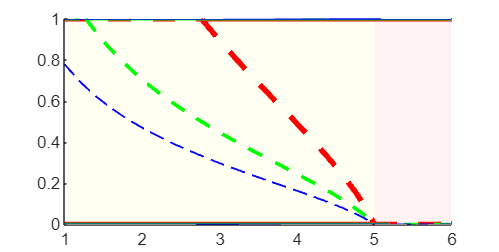

clear all

G = 5;
p = 0.6;
deltas = [0.3, 0.6, 0.9];
colors = {'r', 'g', 'b'};
line_widths = [3,2,1];
r_range = 1:0.001:6;

figure
set(gcf, 'Position', [64, 583, 363, 183]);
hold on;

x1 = [1.02, 5, 5, 1.02];
y1 = [0, 0, 1, 1];
patch(x1, y1, [1 1 0.95], 'EdgeColor', 'none');


x2 = [5, 5.99, 5.99, 5];
y2 = [0, 0, 1, 1];
patch(x2, y2, [1 0.95 0.95], 'EdgeColor', 'none');

for delta_idx = 1:length(deltas)
    delta = deltas(delta_idx);
    color = colors{delta_idx};
    line_width = line_widths(delta_idx);

    % Initializes the variable that stores the data
    solid_x_values = [];
    solid_y_values = [];
    dashed_x_values = [];
    dashed_y_values = [];
    horizontal_line_change_r_0 = 5; % Default value, used if two zeros cannot be found
    horizontal_line_change_r_1 = 6; % Default value, used if the first zero cannot be found
    for r = r_range
        % Definite equation
        eqn = @(x) x * (1 - x) * tanh(((r / G) * (p * (1 + delta * x) ^ (G - 1) + (1 - p) * (1 - delta * x) ^ (G - 1)) - 1) * 0.005);

        % Traverse the x value to find the zero
        x_prev = 0;
        f_prev = eqn(x_prev);
        zero_points = [];
        for x = 0.001:0.001:0.999
            f = eqn(x);
            if f_prev * f < 0 % Change the sign. Find the zero
                zero_points = [zero_points, x]; % Record zero
            end
            x_prev = x;
            f_prev = f;
        end

        % Record data based on the number of zeros found
        if length(zero_points) >= 1
            if horizontal_line_change_r_1 == 6 % Record the r value that finds the first zero first
                horizontal_line_change_r_1 = r;
            end
            if length(zero_points) == 1
                dashed_x_values = [dashed_x_values, r];
                dashed_y_values = [dashed_y_values, zero_points];
            elseif length(zero_points) == 2
                solid_x_values = [solid_x_values, r];
                solid_y_values = [solid_y_values, zero_points(1)];
                dashed_x_values = [dashed_x_values, r];
                dashed_y_values = [dashed_y_values, zero_points(2)];
                % Records the first r value found with two zeros
                if horizontal_line_change_r_0 == 6
                    horizontal_line_change_r_0 = r;
                end
            end
        end
    end
   
    % Create a basic index vector
    basic_indices_x = 1:200:(length(dashed_x_values) - 50);
    basic_indices_y = 1:200:(length(dashed_y_values) - 50);
    
    % Create an index vector that contains the last 50 data
    final_indices_x = (length(dashed_x_values) - 49):length(dashed_x_values);
    final_indices_y = (length(dashed_y_values) - 49):length(dashed_y_values);
    
    % Unmerged index
    indices_x = [basic_indices_x, final_indices_x];
    indices_y = [basic_indices_y, final_indices_y];
    
    % Extract data
    x_matrix = dashed_x_values(indices_x);
    y_matrix = dashed_y_values(indices_y);
    
    % Plotting
    plot(solid_x_values, solid_y_values, [color '-'], 'LineWidth', line_width);
    hold on
    plot(x_matrix, y_matrix, [color '--'], 'LineWidth', line_width);
    hold on
    % Draw a horizontal line corresponding to the vertical axis 0
    plot([1, horizontal_line_change_r_0], [0, 0], [color '-'], 'LineWidth', line_width, 'HandleVisibility','off');
    hold on
    plot([horizontal_line_change_r_0, 6], [0, 0], [color '--'], 'LineWidth', line_width, 'HandleVisibility','off');
    hold on
    % Draw the horizontal line corresponding to the vertical axis of 1
    plot([1, horizontal_line_change_r_1], [1, 1], [color '--'], 'LineWidth', line_width, 'HandleVisibility','off');
    hold on
    plot([horizontal_line_change_r_1, 6], [1, 1], [color '-'], 'LineWidth', line_width, 'HandleVisibility','off');
    
end

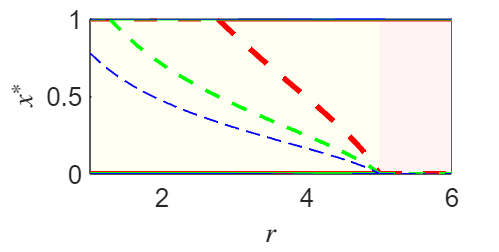


axis([1, 6, 0, 1]);

hold off;

xlabel('${r}$','Interpreter','latex', 'FontSize', 12);
ylabel('${x^*}$','Interpreter','latex', 'FontSize', 12);
set(gca, 'FontName', 'Arial'); 
set(gca, 'FontSize', 14); 
box on;